# API Example Usages (DEPRECIATED - updates in progress. See example.mlx)

### This is a guide for

- creating asset types (component types), assets (components), component models, and UAVs

- loading component models and UAVs

- Performing a simulation with a UAV (choose a random trajectory and fly it)

- Plotting telemetry & powertrain data from the simulation

- displaying summary statistics 

### (Preliminary) Load the workspace paths and connect to database

- To configure the data source, see [https://www.mathworks.com/help/database/ug/configuring-driver-and-data-source.html](https://www.mathworks.com/help/database/ug/configuring-driver-and-data-source.html) 

- go to System DSN, Add, select PostgreSQL ANSI(x64), set the datasource name = uav_db, fill out the rest of the fields and test the connection

% get the root directory
file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), '\');
idx = find(strcmp(file_path, 'uavtestbed'));
root_directory = strjoin(file_path(1:idx), '\')

root_directory = 'G:\Dropbox\NASA\uavtestbed'

% switch to the root directory
cd(root_directory);

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% the database connection, you must implement db_connect()
conn = db_connect('nasadb');
% clear the database connection parameters from the workspace
clear('database_name', 'datasource_name', 'host_name', 'user_name', 'password');

## 1. Creating asset types, assets, component models, and UAVs

- assets are the underlying model that all components inherit from and are created indirectly when a component is created

### Create an asset type

%asset_type = create_asset_type(conn, "airframe", "default", "osmic_2016")

### If the asset type is already created, view the table

statement = "select ast.* from asset_type_tb ast;";
asset_type_tb = select(conn, statement)

asset_type_tb = 4×4 table
    id        type            subtype          description  
    __    ____________    ________________    ______________

    1     {'airframe'}    {'octorotor'   }    {'osmic_2016'}
    3     {'battery' }    {'discrete-eqc'}    {'plett_2015'}
    2     {'motor'   }    {'dc'          }    {'generic'   }
    4     {'uav'     }    {'-'           }    {'-'         }


### Create an airframe

- an airframe is an asset, which is an object type that underlies all components

- note - move airframe sample time (.025)

asset_type    = "airframe";
owner         = "darrahts";
type_id       = find(ismember(asset_type_tb.type(:), asset_type))

type_id = 1

serial_number = sprintf("x%06d", randi(999999));
num_motors    = 8;
age           = 0;
units         = "flight hours";

airframe = create_default_airframe(conn, ...
                                   owner, ...
                                   type_id, ...
                                   serial_number, ...
                                   num_motors, ...
                                   age, ...
                                   units)

airframe = struct with fields:
            id: 634
    num_motors: 8
            ct: 8.5486e-06
            cq: 1.3678e-07
          mass: 1.8000
            Jb: '{0.0429,0,0,0,0.0429,0,0,0,0.0748}'
            cd: 1
           Axy: 0.9000
           Axz: 0.5000
           Ayz: 0.5000
           rho: 1.2000
            lx: 0.2000
            ly: 0.2000
            lz: 0.2000
             l: 0.4500


### Create an airframe with your own parameters

- it is based off the same dynamics model as above, so it uses the same parameters

### Create the motors

- dont forget to create an asset type if it is not already created

%asset_type = create_asset_type(conn, "motor", "dc", "darrah_2020")
asset_type = "motor";
owner      = "darrahts";
type_id    = find(ismember(asset_type_tb.type(:), asset_type));
age        = 0;
units      = "flight hours";

% there are multiple motors
for i=1:airframe.num_motors
    serial_number = sprintf("m%06d", randi(999999));
    motor = create_default_motor(conn, ...
                                 owner, ...
                                 type_id, ...
                                 serial_number, ...
                                 age, ... 
                                 units);
   motors.(sprintf("motor_%d", i)) = motor;
end 
motor 

motor = struct with fields:
              id: 642
    motor_number: NaN
             Req: 0.2371
           Ke_eq: 0.0107
               J: 2.0000e-05
              Df: 0
              cq: 1.3678e-07


### Create the battery (cell)

- the default battery model is a single cell, so to better model battery pack behavior one must create multiple cells and then wire them manually

%asset_type = create_asset_type(conn, "battery", "discrete-eqc", "plett_2015")
asset_type    = "battery";
owner         = "darrahts";
type_id       = find(ismember(asset_type_tb.type(:), asset_type));
serial_number = sprintf("b%06d", randi(999999));
age           = 0;
units         = "cumulative amp hours";

battery = create_default_battery(conn, ...
                                 owner, ...
                                 type_id, ...
                                 serial_number, ...
                                 age, ...
                                 units)

battery = struct with fields:
        id: 643
    cycles: 0
         Q: 15
         G: 163.4413
         M: 0.0092
        M0: 0.0019
        RC: 3.6572
         R: 2.8283e-04
        R0: -0.0011
         n: 0.9987
       EOD: 3.0400
         z: 1
        Ir: 0
         h: 0
         v: 4.2000
        v0: 4.2000
        dt: 1


### Create the UAV

%asset_type = create_asset_type(conn, "uav", "octo", "cube")
asset_type    = "uav";
owner         = "darrahts";
type_id    = find(ismember(asset_type_tb.type(:), asset_type));
serial_number = sprintf("u%06d", randi(999999));
age           = 0;
units         = "flight hours";
fprintf("uav serial number is: %s", serial_number)

uav serial number is: u655741

uav = create_default_uav(conn, ...
                         owner, ...
                         type_id, ...
                         serial_number, ...
                         age, ...
                         units, ...
                         airframe, ...
                         battery, ...
                         motors)

uav = struct with fields:
                 id: 644
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [1×1 struct]
    max_flight_time: 18


## 2. Loading components and the UAV 

#### by serial number which contains the IDs of the components for this specific UAV

uav = load_uav(conn, serial_number)

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [8×1 struct]
    max_flight_time: 18
                 id: 644
               mass: 1.8000


uav.uav

ans = struct with fields:
                 id: 644
              owner: 'darrahts'
            type_id: 4
      serial_number: 'u655741'
                age: 0
                eol: NaN
              units: 'flight hours'
               id_1: 644
        airframe_id: 634
         battery_id: 643
          motor1_id: 635
          motor2_id: 636
          motor3_id: 637
          motor4_id: 638
          motor5_id: 639
          motor6_id: 640
          motor7_id: 641
          motor8_id: 642
    max_flight_time: 18


uav.battery

ans = struct with fields:
         id: 643
     cycles: 0
          Q: 15
          G: 163.4413
          M: 0.0092
         M0: 0.0019
         RC: 3.6572
          R: 2.8283e-04
         R0: -0.0011
          n: 0.9987
        EOD: 3.0400
          z: 1
         Ir: 0
          h: 0
          v: 4.2000
         v0: 4.2000
         dt: 1
    soc_ocv: [1×101 double]


uav.airframe

ans = struct with fields:
            id: 634
    num_motors: 8
            ct: 8.5486e-06
            cq: 1.3678e-07
          mass: 1.8000
            Jb: [3×3 double]
            cd: 1
           Axy: 0.9000
           Axz: 0.5000
           Ayz: 0.5000
           rho: 1.2000
            lx: 0.2000
            ly: 0.2000
            lz: 0.2000
             l: 0.4500


uav.motors

ans = 8×1 struct array with fields:
    id
    owner
    type_id
    serial_number
    age
    eol
    units
    id_1
    motor_number
    Req
    Ke_eq
    J
    Df
    cq


## Data retrieval

### Get a list of UAVs that have completed more than 60 flights

statement = "select count(fst.*) as num_flights, fst.uav_id, ast.serial_number from flight_summary_tb fst join asset_tb ast on fst.uav_id = ast.id group by fst.uav_id, ast.serial_number order by fst.uav_id asc;";
res = select(conn, statement);
res = res(res.num_flights < 200, :);
res = res(res.num_flights > 60, :);
uav_tb = res

uav_tb = 45×3 table
    num_flights    uav_id    serial_number
    ___________    ______    _____________

        84           70       {'u000111'} 
        84           81       {'u000112'} 
        83           92       {'u000113'} 
        82          103       {'u000114'} 
        84          114       {'u000115'} 
        86          137       {'u000116'} 
        85          148       {'u000117'} 
        85          159       {'u000118'} 
        85          170       {'u000119'} 
        80          192       {'u000151'} 
        80          203       {'u000152'} 
        80          214       {'u000153'} 
        79          225       {'u000154'} 
        78          236       {'u000155'} 
        83          279       {'u001201'} 
        79          290       {'u001202'} 


### Bar chart the flight failures

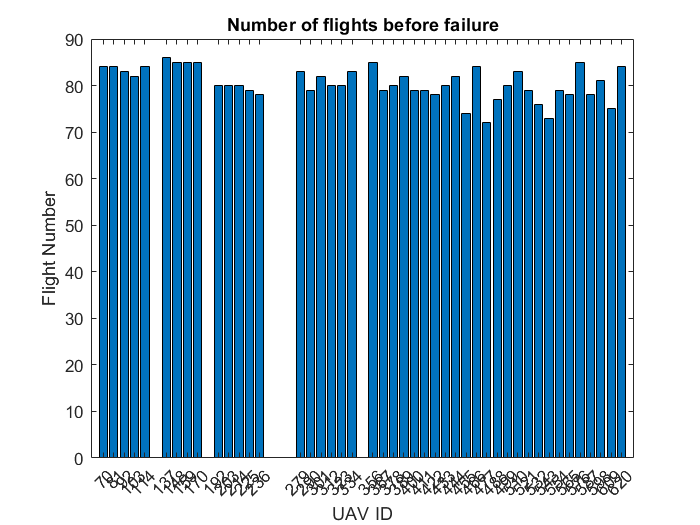

f1 = figure(1); clf;
bar(uav_tb.uav_id, uav_tb.num_flights);
xtickangle(45);
xticks(uav_tb.uav_id);
title("Number of flights before failure");
ylabel("Flight Number");
xlabel("UAV ID");

### Fit a distribution to the failure data & plot

pd = fitdist(uav_tb.num_flights, 'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 80.5333   [79.5075, 81.5592]
    sigma = 3.41454   [2.82674, 4.31325]


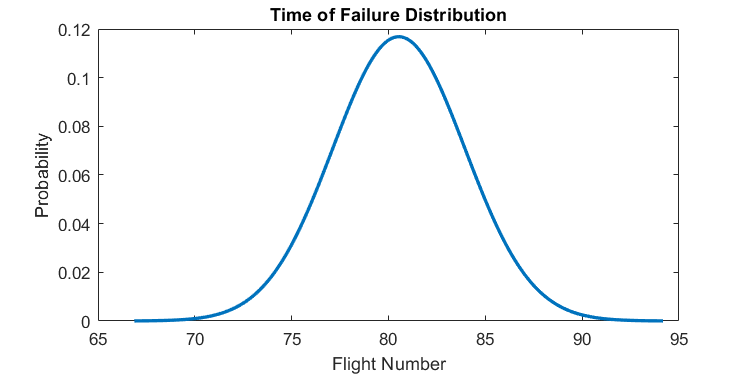

x_range = pd.mu-4*pd.sigma:.1:pd.mu+4*pd.sigma;
failure_distribution = pdf(pd, x_range);
f2 = figure(2); clf;
f2.Position = [0 0 600 300];
plot(x_range, failure_distribution, 'linewidth', 2);
title("Time of Failure Distribution");
ylabel("Probability");
xlabel("Flight Number");

### Look at flight summary and degradation data for a given UAV

uav_idx = 3;
uav_id = uav_tb.uav_id(uav_idx)

uav_id = int32
92

uav_serial_number = string(uav_tb.uav_id(uav_idx))

uav_serial_number = "92"

statement = sprintf("select fst.*, fdt.* from flight_summary_tb fst join flight_degradation_tb fdt on fst.id = fdt.flight_id where fst.uav_id = %d;", uav_id);
res = select(conn, statement)

res = 83×34 table
    id     stop_code     z_end     v_end     avg_pos_err    max_pos_err    std_pos_err    avg_ctrl_err    max_ctrl_err    std_ctrl_err    distance    flight_time    avg_current    amp_hours           dt_start                    dt_stop            trajectory_id    uav_id    flight_num    id_1    flight_id    q_deg     q_var     q_slope     q_intercept      r_deg        r_var       r_slope      r_intercept     m_deg     m_var      m_slope

### Plot the system performance parameters

- z_end (state of charge)

- v_end (output voltage)

- avg_pos_err (average position error over the entire flight)

- std_pos_err (standard deviation of the position error of an entire flight)

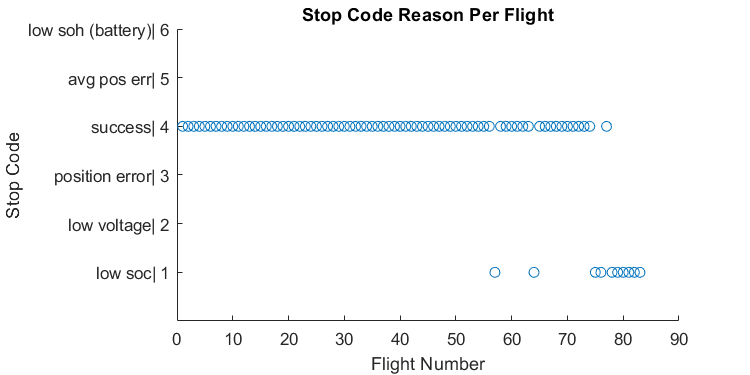

f20 = figure(20); clf;
f20.Position = [0 0 600 300];
scatter(1:1:length(res.stop_code), res.stop_code)
ylim([0 6]);
xlabel('Flight Number');
ylabel('Stop Code');
yticklabels({" ", "low soc| 1", "low voltage| 2", "position error| 3", "success| 4", "avg pos err| 5", "low soh (battery)| 6"}); 
title("Stop Code Reason Per Flight")

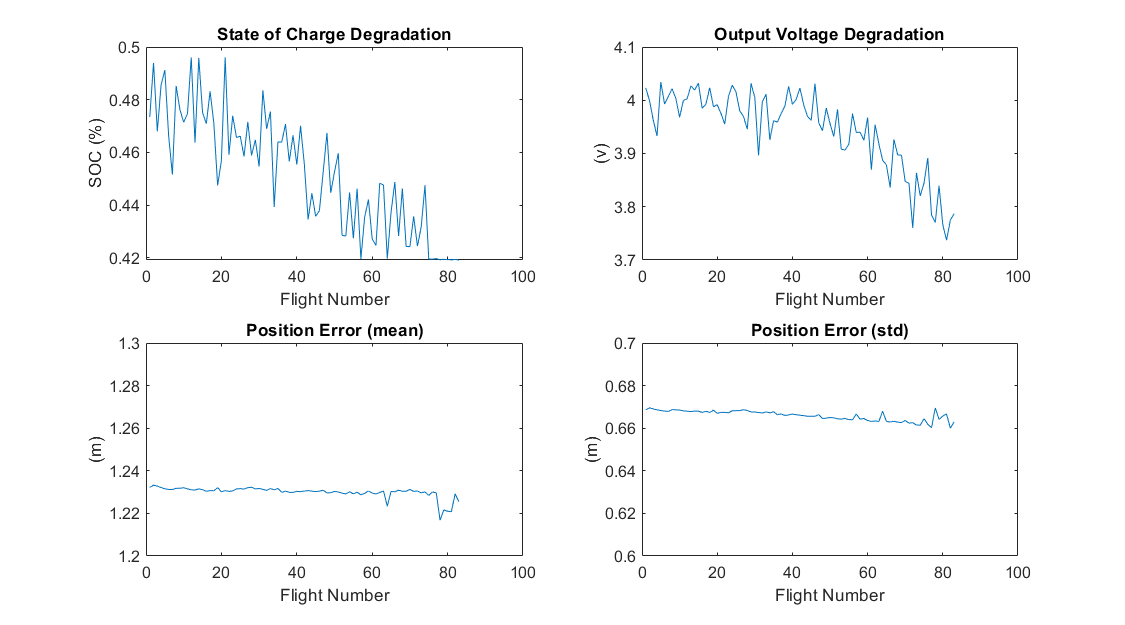

f2 = figure(2); clf;
f2.Position = [0 0 900 500];
subplot(2,2,1);
plot(res.z_end)
title("State of Charge Degradation")
ylabel("SOC (%)")
xlabel("Flight Number")

subplot(2,2,2);
plot(res.v_end);
title("Output Voltage Degradation")
ylabel("(v)")
xlabel("Flight Number")

subplot(2,2,3);
plot(res.avg_pos_err);
title("Position Error (mean)")
ylabel("(m)")
xlabel("Flight Number")
ylim([1.2 1.3]);

subplot(2,2,4);
plot(res.std_pos_err);
title("Position Error (std)")
ylabel("(m)")
xlabel("Flight Number")
ylim([.6 .7]);

### Plot component degradation parameters

- q_deg (battery capacitance)

- r_deg (battery internal resistance)

- m_deg (motor resistance)

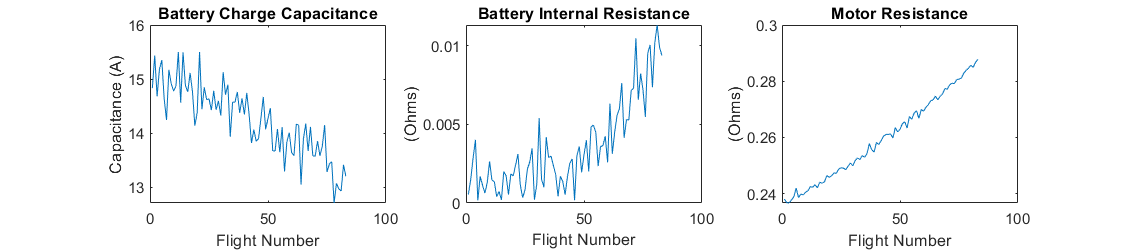

f3 = figure(3); clf;
f3.Position = [0 0 900 200];
subplot(1,3,1);
plot(res.q_deg)
title("Battery Charge Capacitance")
ylabel("Capacitance (A)")
xlabel("Flight Number")

subplot(1,3,2);
plot(res.r_deg);
title("Battery Internal Resistance")
ylabel("(Ohms)")
xlabel("Flight Number")

subplot(1,3,3);
plot(res.m_deg);
title("Motor Resistance")
ylabel("(Ohms)")
xlabel("Flight Number")

### Perform a simulation with a UAV

open example.mlx;

### Plot telemetry data from a single flight

%% TODO

## Plot data from multiple UAVs

- aggregate flight summary and degradation data across all of the UAVs by mission

- use uav_tb

uav_tb

uav_tb = 45×3 table
    num_flights    uav_id    serial_number
    ___________    ______    _____________

        84           70       {'u000111'} 
        84           81       {'u000112'} 
        83           92       {'u000113'} 
        82          103       {'u000114'} 
        84          114       {'u000115'} 
        86          137       {'u000116'} 
        85          148       {'u000117'} 
        85          159       {'u000118'} 
        85          170       {'u000119'} 
        80          192       {'u000151'} 
        80          203       {'u000152'} 
        80          214       {'u000153'} 
        79          225       {'u000154'} 
        78          236       {'u000155'} 
        83          279       {'u001201'} 
        79          290       {'u001202'} 


### Cache the data tables (not telemetry data)

- flight summary data

- flight degradation data

- frequency of data is once per flight (at the end of a mission)

for i=1:height(uav_tb)
    uav_id = uav_tb.uav_id(i);
    statement = sprintf("select fst.*, fdt.* from flight_summary_tb fst join flight_degradation_tb fdt on fst.id = fdt.flight_id where fst.uav_id = %d;", uav_id);
    flight_data_tables.(sprintf("uav_%d", uav_id)) = select(conn, statement);
end

### Generate distributions of the system performance parameters

- z_end (state of charge)

- v_end (output voltage)

- avg_pos_err (average position error over the entire flight)

- std_pos_err (standard deviation of the position error of an entire flight)

** The distributions are**

- an array of mean values for the state of charge of each UAV across each mission number (from 1,2,3...)

- an array of standard deviation values

**UAV failures do not occur at the same time so calculate up the earliest failure**

earliest_failure = min(uav_tb.num_flights)

earliest_failure = int64
72

**Get system performance data**

for i=1:height(uav_tb)
    uav_id = uav_tb.uav_id(i);
    std_pos_errs{i} = [flight_data_tables.(sprintf("uav_%d", uav_id)).std_pos_err];
    avg_pos_errs{i} = [flight_data_tables.(sprintf("uav_%d", uav_id)).avg_pos_err];
    v_ends{i}       = [flight_data_tables.(sprintf("uav_%d", uav_id)).v_end];
    z_ends{i}       = [flight_data_tables.(sprintf("uav_%d", uav_id)).z_end];
    soc_chargeds{i} = [flight_data_tables.(sprintf("uav_%d", uav_id)).q_deg];
end

Accessing the data is illustrated by the following example

i = 3;
j = 9;
uav_tb.uav_id(i)

ans = int32
92

z_ends{i}(j)

ans = single
0.4762

this is the ending state of charge of the 3rd uav with id of 92 on its 9th mission 

z_means = zeros(earliest_failure, 1);
z_stds = zeros(earliest_failure, 1);
z_end_vals = zeros(height(uav_tb), 1);
z_end_data = struct;

v_means = zeros(earliest_failure, 1);
v_stds = zeros(earliest_failure, 1);
v_end_vals = zeros(height(uav_tb), 1);
v_end_data = struct;

avg_pos_err_means = zeros(earliest_failure, 1);
avg_pos_err_stds = zeros(earliest_failure, 1);
avg_pos_err_vals = zeros(height(uav_tb), 1);
avg_pos_err_data = struct;

std_pos_err_means = zeros(earliest_failure, 1);
std_pos_err_stds = zeros(earliest_failure, 1);
std_pos_err_vals = zeros(height(uav_tb), 1);
std_pos_err_data = struct;

sc_means = zeros(earliest_failure, 1);
sc_stds = zeros(earliest_failure, 1);
soc_charged_vals = zeros(height(uav_tb), 1);
soc_charged_data = struct;

for j=1:earliest_failure
    
    for i=1:height(uav_tb)
        z_end_vals(i) = z_ends{i}(j);
        v_end_vals(i) = v_ends{i}(j);
        avg_pos_err_vals(i) = avg_pos_errs{i}(j);
        std_pos_err_vals(i) = std_pos_errs{i}(j);
        soc_charged_vals(i) = soc_chargeds{i}(j);
    end
    
    % state of charge (fully charged)
    sc_pd = fitdist(soc_charged_vals, 'Normal');
    sc_means(j) = sc_pd.mu;
    sc_stds(j) = sc_pd.sigma;
    
    if j == 1 || j == 25 || j == 50 || j == earliest_failure
        sc_x_range = sc_pd.mu-4*sc_pd.sigma:.001:sc_pd.mu+4*sc_pd.sigma;
        sc_pdf_vals = pdf(sc_pd, sc_x_range);
        soc_charged_data.(sprintf("flight_%d", j)) = {sc_x_range; sc_pdf_vals};
    end
    
    
    % state of charge
    z_pd = fitdist(z_end_vals, 'Normal');
    z_means(j) = z_pd.mu;
    z_stds(j) = z_pd.sigma;
    
    if j == 1 || j == 25 || j == 50 || j == earliest_failure
        z_x_range = z_pd.mu-4*z_pd.sigma:.001:z_pd.mu+4*z_pd.sigma;
        z_pdf_vals = pdf(z_pd, z_x_range);
        z_end_data.(sprintf("flight_%d", j)) = {z_x_range; z_pdf_vals};
    end
    
    % output voltage
    v_pd = fitdist(v_end_vals, 'Normal');
    v_means(j) = v_pd.mu;
    v_stds(j) = v_pd.sigma;
    
    if j == 1 || j == 25 || j == 50 || j == earliest_failure
        v_x_range = v_pd.mu-4*v_pd.sigma:.001:v_pd.mu+4*v_pd.sigma;
        v_pdf_vals = pdf(v_pd, v_x_range);
        v_end_data.(sprintf("flight_%d", j)) = {v_x_range; v_pdf_vals};
    end
    
    % average pos error
    avg_pos_err_pd = fitdist(avg_pos_err_vals, 'Normal');
    avg_pos_err_means(j) = avg_pos_err_pd.mu;
    avg_pos_err_stds(j) = avg_pos_err_pd.sigma;
    
    if j == 1 || j == 25 || j == 50 || j == earliest_failure
        avg_pos_err_x_range = avg_pos_err_pd.mu-4*avg_pos_err_pd.sigma:.0001:avg_pos_err_pd.mu+4*avg_pos_err_pd.sigma;
        avg_pos_err_pdf_vals = pdf(avg_pos_err_pd, avg_pos_err_x_range);
        avg_pos_err_data.(sprintf("flight_%d", j)) = {avg_pos_err_x_range; avg_pos_err_pdf_vals};
    end
    
    % standard deviation pos error
    std_pos_err_pd = fitdist(std_pos_err_vals, 'Normal');
    std_pos_err_means(j) = std_pos_err_pd.mu;
    std_pos_err_stds(j) = std_pos_err_pd.sigma;
    
    if j == 1 || j == 25 || j == 50 || j == earliest_failure
        std_pos_err_x_range = std_pos_err_pd.mu-4*std_pos_err_pd.sigma:.0001:std_pos_err_pd.mu+4*std_pos_err_pd.sigma;
        std_pos_err_pdf_vals = pdf(std_pos_err_pd, std_pos_err_x_range);
        std_pos_err_data.(sprintf("flight_%d", j)) = {std_pos_err_x_range; std_pos_err_pdf_vals};
    end
    
    
end

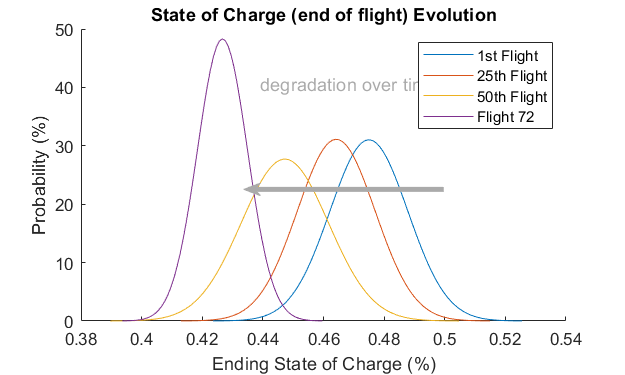

f5 =   Figure (95751) with properties:

      Number: 95751
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f5 = dist_plot_1(z_end_data, [1 25 50 earliest_failure], 'z')

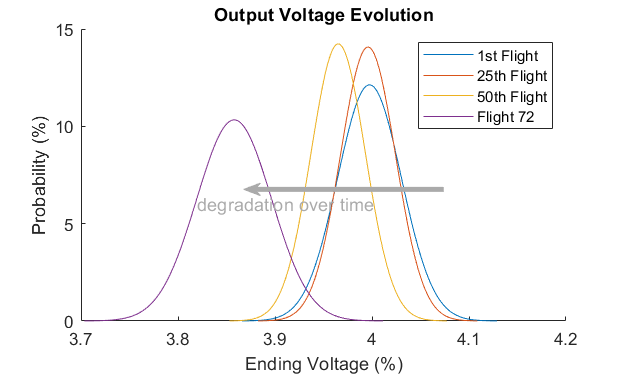

f6 =   Figure (96489) with properties:

      Number: 96489
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f6 = dist_plot_1(v_end_data, [1 25 50 earliest_failure], 'v')

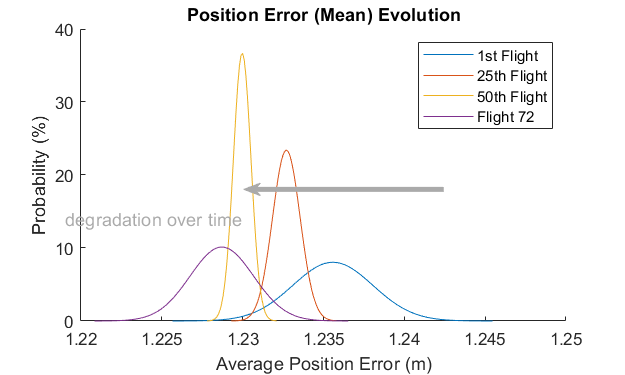

f7 =   Figure (15762) with properties:

      Number: 15762
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties



f7 = dist_plot_1(avg_pos_err_data, [1 25 50 earliest_failure], 'a')

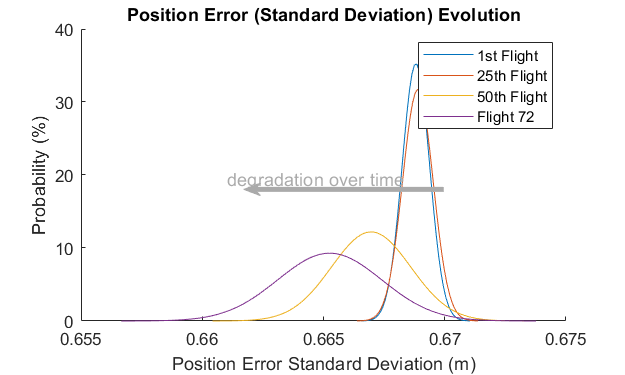

f8 =   Figure (97060) with properties:

      Number: 97060
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f8 = dist_plot_1(std_pos_err_data, [1 25 50 earliest_failure], 's')

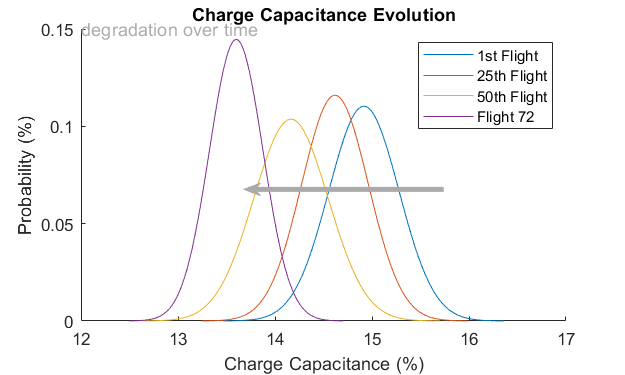

f9 =   Figure (95717) with properties:

      Number: 95717
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f9 = figure(9); clf
f9 = dist_plot_1(soc_charged_data, [1 25 50 earliest_failure], 'c')

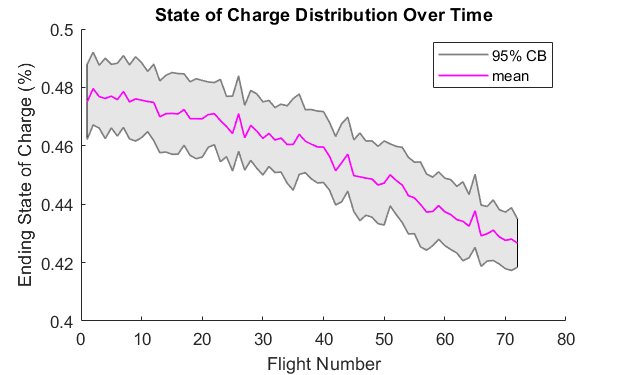

f10 =   Figure (48538) with properties:

      Number: 48538
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f10 = dist_plot_2(z_means, z_stds, 'z', earliest_failure)

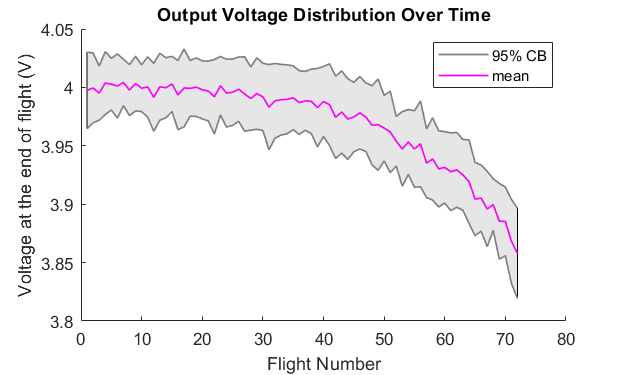

f11 =   Figure (80029) with properties:

      Number: 80029
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f11 = dist_plot_2(v_means, v_stds, 'v', earliest_failure)

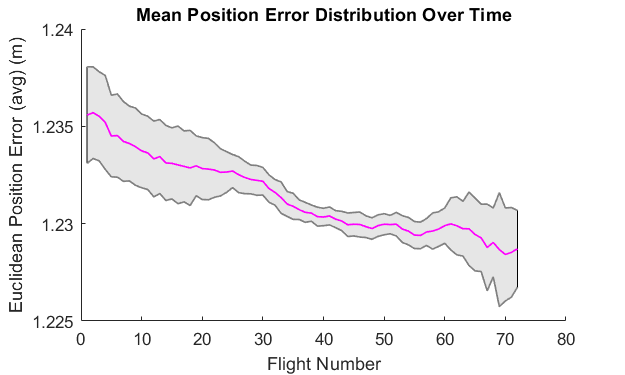

f12 =   Figure (14189) with properties:

      Number: 14189
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f12 = dist_plot_2(avg_pos_err_means, avg_pos_err_stds, 'a', earliest_failure)

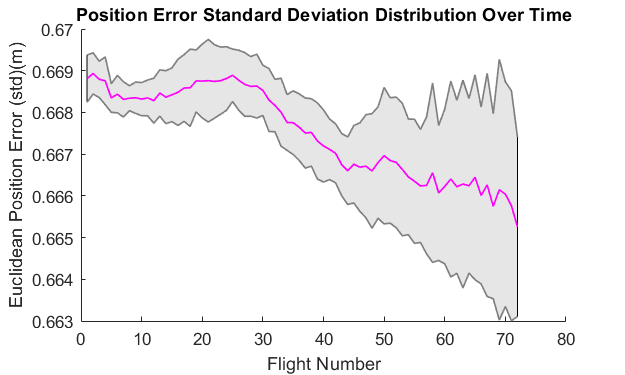

f13 =   Figure (42177) with properties:

      Number: 42177
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f13 = dist_plot_2(std_pos_err_means, std_pos_err_stds, 's', earliest_failure)

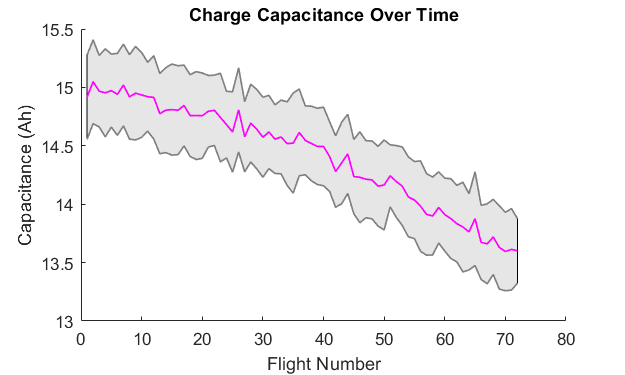

f14 =   Figure (91574) with properties:

      Number: 91574
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 500 300]
       Units: 'pixels'

  Show all properties


f14 = dist_plot_2(sc_means, sc_stds, 'q', earliest_failure)

## Load the processes

- degradation (battery capacitance, battery resistance, motor resistance)

- environment (temperature, wind)

statement = {"select ptt.id as process_type_id,"
            'ptt."type" as process_type,'
            "ptt.subtype1,"
            "ptt.subtype2,"
            "ast.id as asset_type_id,"
            'ast."type" as asset_type,'
            "ast.subtype,"
            "ast.description as model_source,"
            "pst.id as process_id,"
            "pst.description,"
            'pst."source" as degradation_source,'
            "pst.parameters "
            "from process_type_tb ptt "
            "inner join process_tb pst on pst.type_id = ptt.id "
            "inner join asset_type_tb ast "
            "on ptt.asset_type_id = ast.id;"};
   statement = sprintf('%s\n',statement{:});
   process_tb = select(conn, statement);
for i = 1:height(process_tb)
    process = strsplit(string(process_tb.parameters{i}(2:end-1)), ':');
    deg_name = erase(process(1), '"')
    process(2) = erase(process(2), ' ');
    process(2) = erase(process(2), '[');
    process(2) = erase(process(2), ']');
    deg_vals = str2num(process(2));
    processes.(sprintf("%s", process_tb.process_type{i})).(sprintf("%s", strrep(process_tb.subtype1{i}, '-', '_'))).(sprintf("%s", deg_name)) = deg_vals
end

deg_name = "qdeg"

processes = struct with fields:
    degradation: [1×1 struct]
    environment: [1×1 struct]


deg_name = "rdeg"

processes = struct with fields:
    degradation: [1×1 struct]
    environment: [1×1 struct]


deg_name = "mdeg"

processes = struct with fields:
    degradation: [1×1 struct]
    environment: [1×1 struct]


deg_name = "x"

processes = struct with fields:
    degradation: [1×1 struct]
    environment: [1×1 struct]


browse_struct(processes)

ans = struct with fields:
    degradation: [1×1 struct]
    environment: [1×1 struct]


function initStruct = browse_struct(initStruct)

    fields = fieldnames(initStruct);
    n_fields = length(fields);

    for n = 1 : n_fields
        val = initStruct.(fields{n});
        if isstruct(val)
            initStruct.(fields{n}) = browse_struct(val);
        elseif( ischar(val) && val(1)=='$' )
            newVal = replace_keyword(val);
            initStruct.(fields{n}) = newVal;
        end
    end

end 